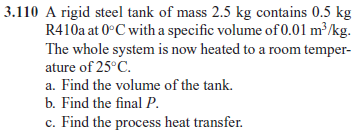

# symbolic units class

u = symunit;
mst = 2.5*u.kg;
Cst = 0.46*u.kJ/(u.kg*u.Celsius);

# state 1 (liquid-vapor R-410a mix)

% -------------------------
% given
m1 = 0.5*u.kg;
p1 = 798.7*u.kPa;
T1 = 0; % degrees Celsius
v1 = 0.01*u.m^3/u.kg;
% -------------------------
% tank volume
Vol1 = m1*v1;
Vol1_vpa = vpa(Vol1) %#ok

$$Vol1\_vpa = 0.005\,m^{3}$$

clear Vol1_vpa;
% -------------------------
% quality
vf1 = 0.000855*u.m^3/u.kg;
vfg1 = 0.03182*u.m^3/u.kg;
x1 = (v1-vf1)/vfg1;
% -------------------------
% specific internal energy
uf1 = 57.07*u.kJ/u.kg;
ufg1 = 195.95*u.kJ/u.kg;
u1 = uf1+x1*ufg1;
% -------------------------

# state 2 (liquid-vapor R-410a mix)

% -------------------------
% given
m2 = m1;
Vol2 = Vol1;
v2 = v1;
p2 = 1653.6*u.kPa;
T2 = 25*u.Celsius;
% -------------------------
% quality
vf2 = 0.000944*u.m^3/u.kg;
vfg2 = 0.01420*u.m^3/u.kg;
x2 = (v2-vf2)/vfg2;
% -------------------------
% specific internal energy
uf2 = 96.03*u.kJ/u.kg;
ufg2 = 162.95*u.kJ/u.kg;
u2 = uf2+x2*ufg2;
% -------------------------

# work done

W_12 = 0; % because the volume is constant

# heat transfer

Q_12 = m2*u2-m1*u1+mst*Cst*(T2-T1);
Q_12_vpa = vpa(Q_12, 4) %#ok

$$Q\_12\_vpa = 72.03\,\mathrm{kJ}$$

clear Q_12_vpa